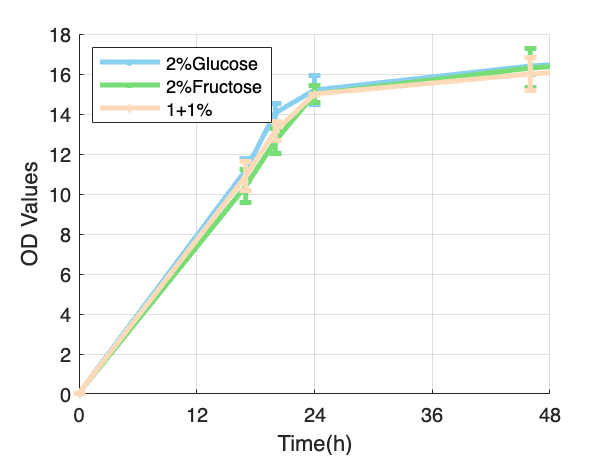

% 1. Read the Data from Excel
filename = 'WT S.B Growth Curve Data.xlsx'; % replace with your file path
[data, text] = xlsread(filename); % 'text' contains header info

time = data(:, 1); % Time data from column A
conditions = data(:, 2:7); % OD values for the 6 sugar conditions

% 2. Define the Colors for Plotting
colors = {'#89CFF0', '#77DD77', '#FFDAB9'}; % Colors for groups B&C, D&E, F&G 

% Define different marker symbols
markers = {'o', 's', 'd'}; % circle, square, diamond

% 3.1 Calculate Standard Deviations
numGroups = 3; % Since you have 6 columns and want to group every two columns
stdValues = zeros(length(time), numGroups); % Pre-allocate for efficiency

for i = 1:numGroups
    col1 = conditions(:, 2*i-1); % First column of the group
    col2 = conditions(:, 2*i);   % Second column of the group
    stdValues(:, i) = std([col1, col2], 0, 2); % Standard deviation along rows
end

% 3.2 Plot the Growth Curves with Connected Dots and Error Bars
figure;
hold on;

for i = 1:numGroups
    groupMean = mean([conditions(:, 2*i-1), conditions(:, 2*i)], 2); % Average for each time point
    errorbar(time, groupMean, stdValues(:, i), 'Color', colors{i}, 'Marker', markers{i}, 'MarkerSize', 1, 'LineWidth', 2.5);
end

% Custom legend with updated dummy plots
h(1) = plot(NaN,NaN, '-o', 'Color', '#89CFF0', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for B & C (Soft Blue)
h(2) = plot(NaN,NaN, '-s', 'Color', '#77DD77', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for D & E (Pastel Green)
h(3) = plot(NaN,NaN, '-d', 'Color', '#FFDAB9', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for F & G (Pale Orange)

legendEntries = {
    [text{1, 2}]; 
    [text{1, 4}];
    [text{1, 6}]
};
legend(h, legendEntries, 'Location', 'northwest');

% 4. Customize the Graph
%title('S.B Growth Curve under Different Sugar Conditions');
xlabel('Time(h)');
ylabel('OD Values');
grid on;

% Set x-axis limits and ticks
xlim([0 48]);
xticks(0:12:60);

% 5. Save the Graph (optional)
saveas(gcf, 'WT_S.B_growth_curve_plot.png'); % saves the graph as a PNG image